# Exercise 2: Setup Estimation Filter to Track A Single Piece of Space Debris

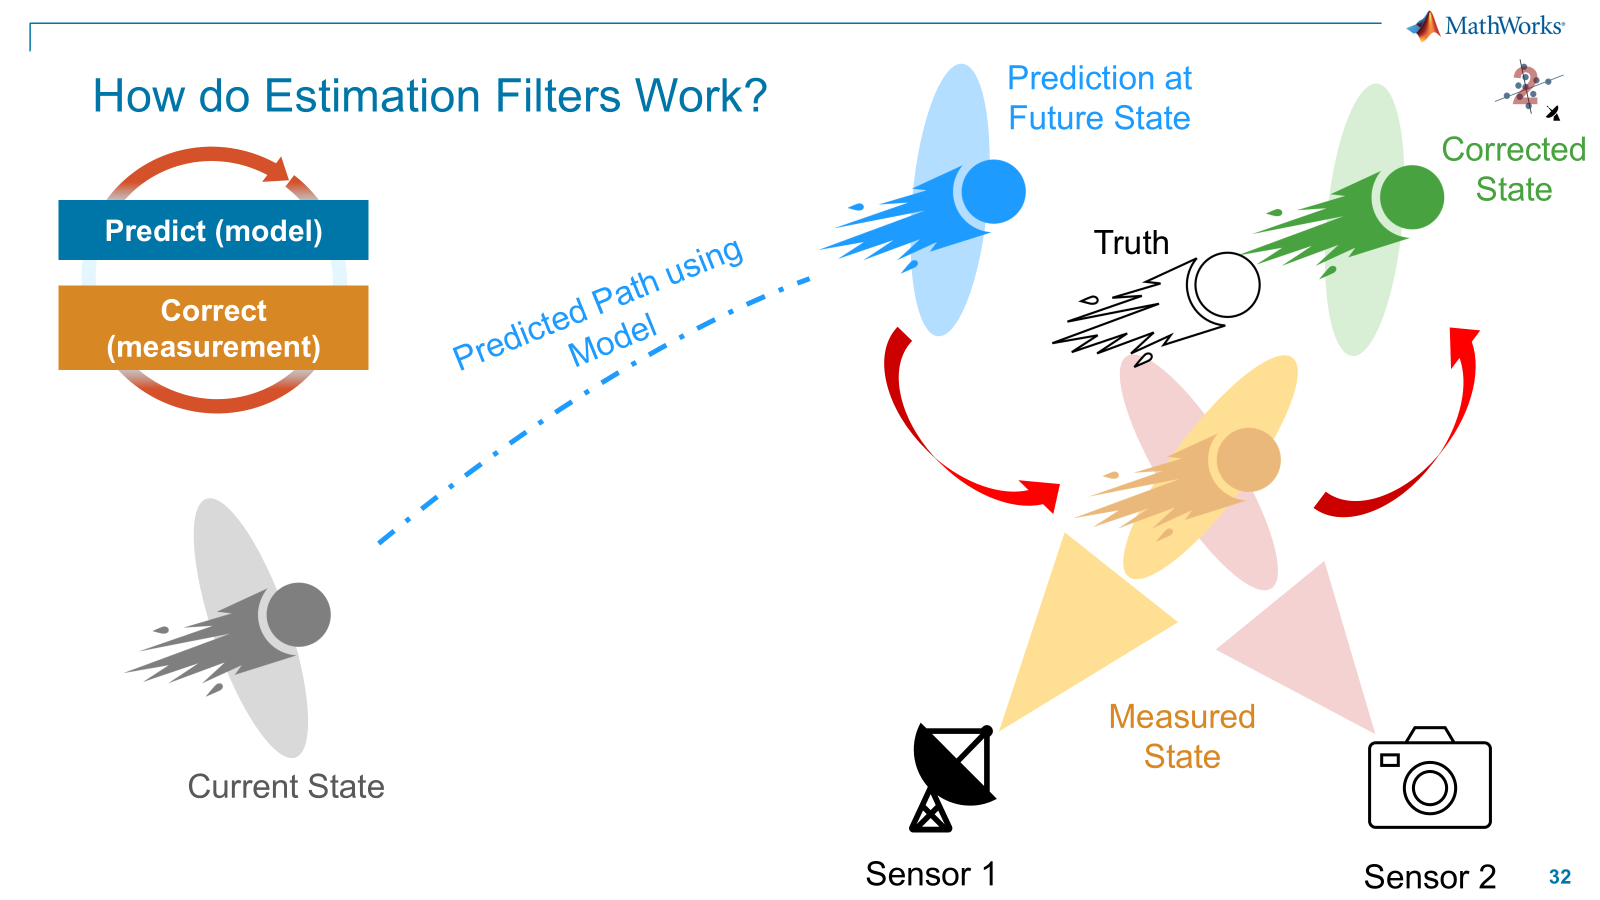

*Note: In the above diagram, we show two sensors, but for this exercise we are only using a single set of detections (implying a single sensor) for simplicity.*

When tracking space debris (or any target), estimation filters are commonly used to estimate the **state** of the object.  For tracking applications, a target's **state** commonly consists of some combination of position, velocity, and acceleration. Estimation filters leverage detections (often from sensor measurements), a motion model, and state update equation to predict and correct the future state of the system.

Generally, **Estimation Filters **capture the:

    1) Dynamics of the system via a prediction model (gives the **predicted state**), including the uncertainty of system dynamics (**process noise**) - these are used in the **prediction** step.

    2) Measurements (**detections**), including the uncertainty of the measurements (**measurement noise**) - these are used in the **correction** step.

Application of a Kalman Filter iteratively updates the filters parameters to increase accuracy of the filter's corrected estimate via the "predict, measure, correct" loop, illustrated below.

For more information on state estimation filters, check this documentation page: [Introduction to Estimation Filters](https://www.mathworks.com/help/fusion/ug/introduction-to-estimation-filters.html). Especially, take a look at the flowchart at the bottom of the "Filter Design" section.

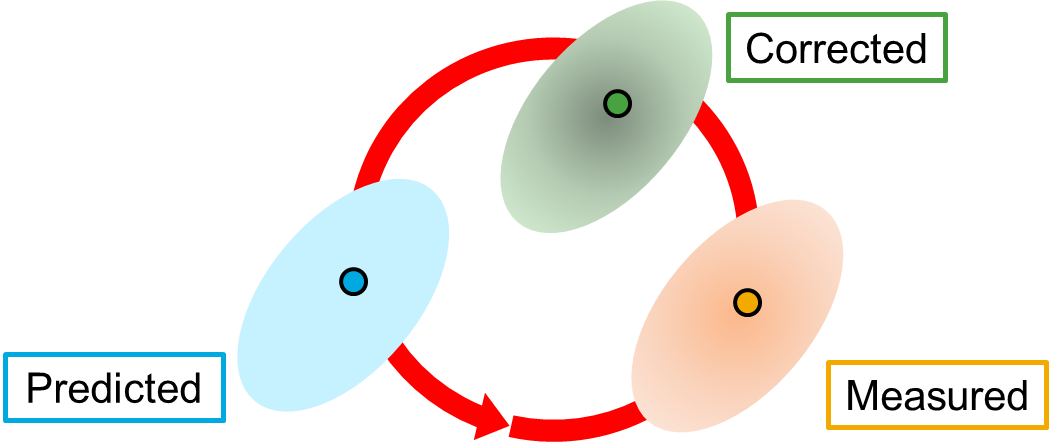

Filters take many forms, but one common filter is the **Extended Kalman Filter**, which we will use in this example. Specifically, we use a constant acceleration extended kalman filter. For more information on the Extended Kalman Filter, please check this documentation page: [Extended Kalman Filters.](https://www.mathworks.com/help/releases/R2024b/fusion/ug/extended-kalman-filters.html)

By using the default values for a "trackingEKF" filter by using the "initcvekf" function in Part 2a, we see that our predicted and corrected values are far from the true positions. Remember! These detections are space debris orbiting earth, so the path of the target is long. If our predictions and corrections don't appear almost exactly over the truth from this vantage point, they must be very far from the truth - on the order distance defined by the space between xticks and yticks in the plot. We can see that our default filter is not well-tuned to the data. **But how bad is it?**

We can use the Mahalanobis Distance to estimate how accurate (or not!) our predicted and corrected positions are.  The Mahalanobis Distance is a measure between a sample point and a distribution, often used within trackers. The calculation for the Mahalanobis Distance is within the helper function "helperCalcMahalanobisDist" at the bottom of this script, if you are interested in the equation, please see [this documentation page](https://www.mathworks.com/help/releases/R2024b/stats/mahal.html?searchPort=58770#d126e790178).

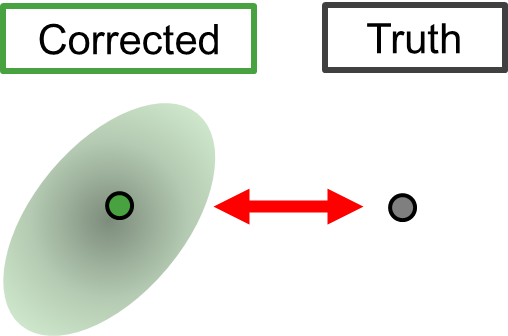

The Mahalanobis Distance is a value relative to a distribution, so a value of 1 means the value of interest (**corrected state**) is 1 standard deviation away from the base value (**truth** **state**).  We see that in our plot for the default filter, the **Mahalanobis Distances are very large**.

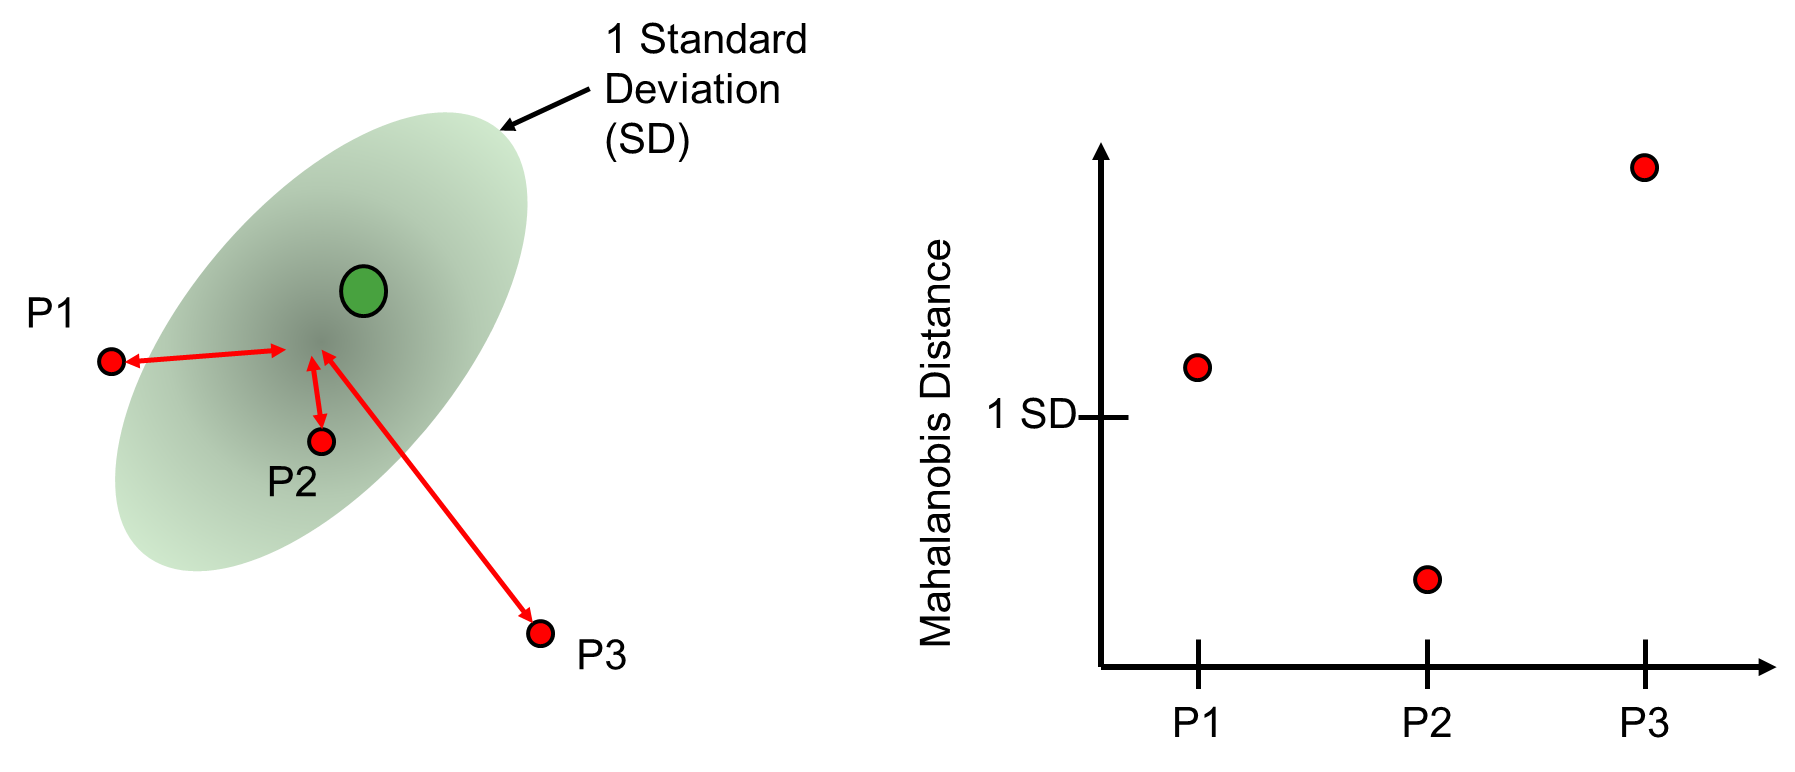

**Exercise 2a: State Estimation Using Default initcvekf - Where will the debris be in one time step?**

First, let's test how the default constant acceleration extended kalman filter performs on our dataset for a single piece of space debris.

We can clear our workspace and command window and also close all open figures with the commands below:

clear; clc; close all;

Let's load in our truth and detection data from the previous example:

S = load('SpaceDebrisLEO_1Target.mat');
truthPosition = S.truthPos;       % Truth Position - where the target actually is
detectionPosition = S.detPos;     % Detection Position - where the target was detected
time = S.time;
objectDetection = S.objDet;       % Object Detection as an "object detection object"
speed = S.speed;
initialDetection = objectDetection{1};

Now, let's define a filter.

Coding Directions:

Please create a variable 'filter' that holds the default Constant Acceleration Extended Kalman Filter (EKF) estimation filter. Define the estimation filter using a "initcvekf" filter. This filter initialization function requires a detection as input. Pass the "initialDetection" to "initcvekf".

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% WRITE YOUR CODE HERE:
% type "doc initcvekf" in the Command Window to find the documentation page for this function
filter = initcvekf(initialDetection);
% This filter runs with default inputs
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

**Plot Detections, Predictions, and Corrections**

Loop through the detection data via the time vector to plot detections, predictions, and corrections as the target moves through the space.

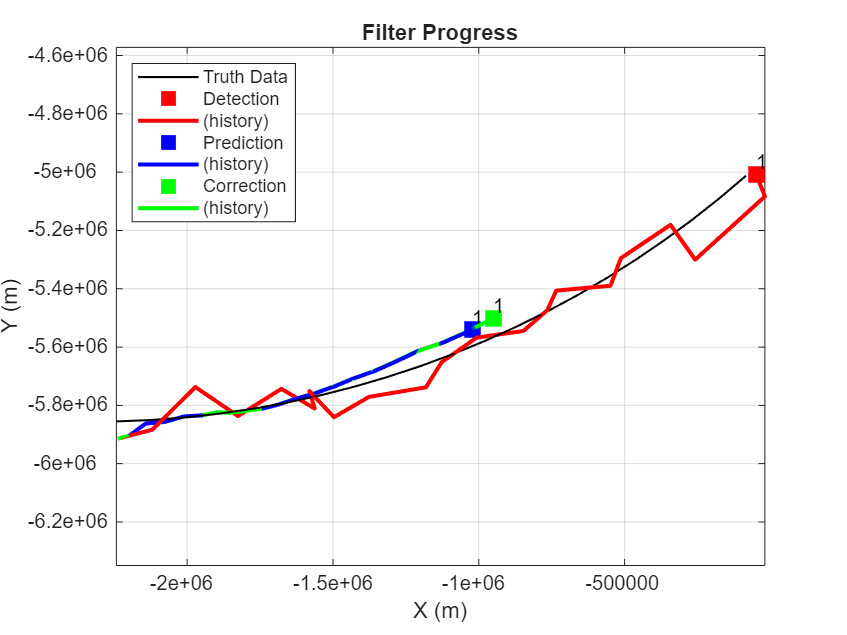

mahalanobisDist = helperRunDataLoop_CV(detectionPosition,truthPosition,filter,time,objectDetection{1}.MeasurementNoise);

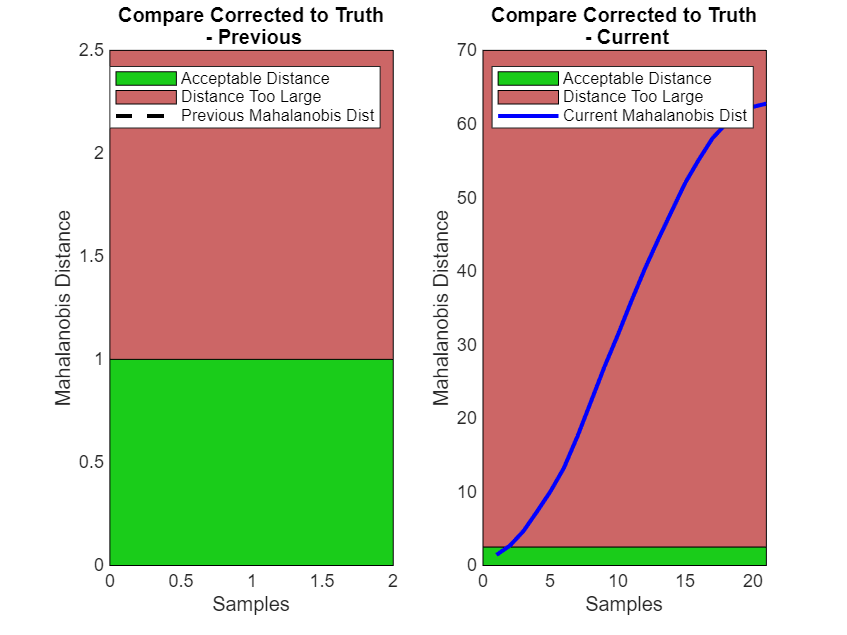

mahalanobisDistanceDefault  = helperPlotMahalanobisDist(mahalanobisDist,0);

**Exercise 2b: Improve State Estimation by Adjusting Filter Settings **

**With the default settings, we see that our predicted and corrected values don't match our data. What do we do now?**

To improve our filter, there are a few things we can do:

        a) Our detections do not include velocity, so the assumed velocity is 0m/s.  We can include a known velocity in our **initial state** estimate to anchor the filter closer to the true motion of the space debris.

        b) Edit values within the **state covariance** matrix to better match the dynamics of the system.  In our constant velocity case, if the filter assumes the target moves slower than it does, the filter may have a tough time predicting the subsequent position of our target.

        c) Adjust the **Process Noise **to incorporate the error associated with motion model. Because our filter has already incorporated the measurement noise defined by the detection data, but we have left the process noise as default values, the filter is overly confident in the motion model. By increasing the process noise, we achieve a better balance between motion model and measurements.

So let's do it!

**Information Provided by Tracking Engineer:**

knownVelo = 7.5e3; % m/s - Estimate of Space Debris Velocity
initialState = [detectionPosition(1,1) knownVelo detectionPosition(2,1) knownVelo detectionPosition(3,1) knownVelo]'; % 3D position of first detection plus the known velocity of space debris
initialStateCovariance = blkdiag(detectionMeasurementNoise(1)^2,knownVelo^2,...
    detectionMeasurementNoise(1)^2,knownVelo^2,...
    detectionMeasurementNoise(1)^2,knownVelo^2);
processNoise = blkdiag(1,1,1)*10^3;

Setup a new tracker:

filter = initcvekf(initialDetection);

**Update Filter Settings to Improve State Estimation**

There are four (4) parameters of the filter to change, directions are enumerated a though d below.

Coding Directions: 

a) Use the variable "initialState" to assign the initial position from the detection data and an estimate of space debris velocity to the** state** of the filter.

Once the filter is initialized, the initial state of the filter is stored in the filter's state. You can access this property using "filter.State". 

b)  Assign the initial **state covariance** matrix to the current state covariance stored within the filter. This can be done using the value in the variable "initialStateCovariance" above. You can access this property using "filter.StateCovariance". 

c) Assign the **process noise** given to you by the tracking engineer to the process noise of the filter.  This can be done using the value stored in the variable "processNoise" above.  You can access this property using "filter.ProcessNoise".

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% WRITE YOUR CODE HERE:
% type "doc trackerEKF" in the Command Window to find the documentation
% page for this function and look for the "State" Property 
filter.State = initialState; % Task A
filter.StateCovariance = initialStateCovariance; % Task B
filter.ProcessNoise = processNoise; % Task C
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Print out the new initial state estimate (this can optionally be done for each of the parameters we just updated):

disp(filter.State)

   1.0e+06 *

   -2.2382
    0.0075
   -5.9142
    0.0075
    2.5264
    0.0075



Run through data loop:

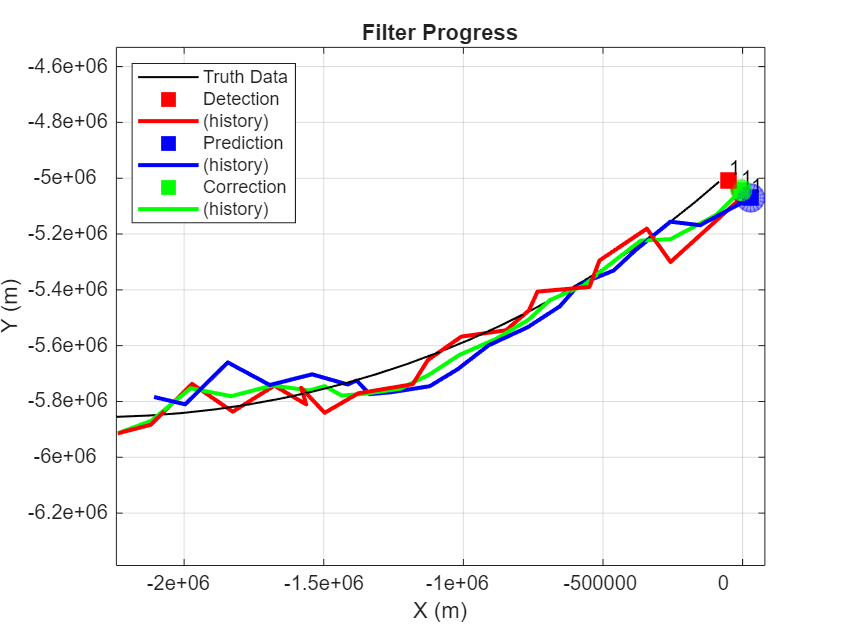

mahalanobisDist = helperRunDataLoop_CV(detectionPosition,truthPosition,filter,time,objectDetection{1}.MeasurementNoise);

 Plot Mahalanobis Distance

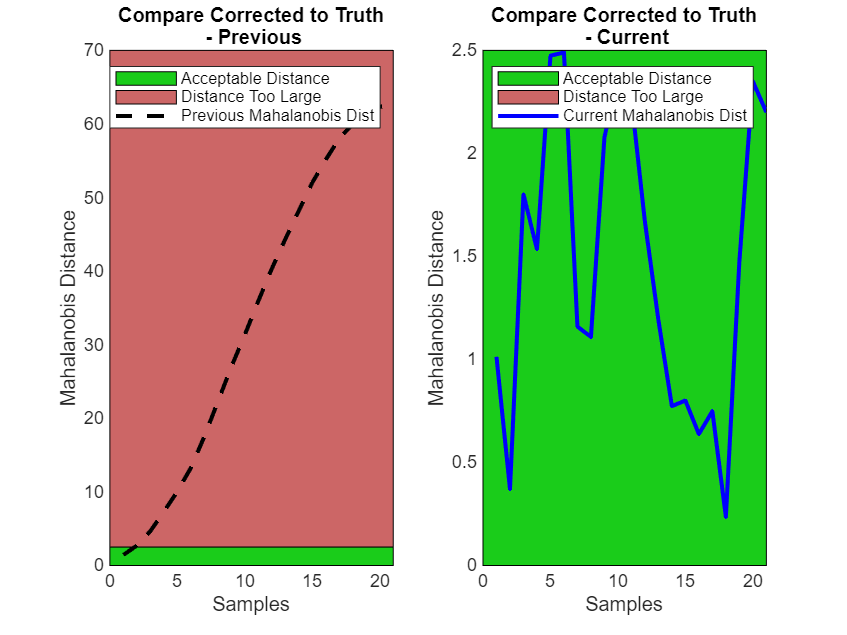

helperPlotMahalanobisDist(mahalanobisDist,mahalanobisDistanceDefault);

**Exercise 2c: Leverage a Tuned Filter to Estimate the State**

In our case, our dataset is made from simulated truth positions of our targets, which can be leveraged as truth data.  This makes filter tuning possible. For this exercise, we have performed the tuning for you.

Coding Directions

Leverage the "tunedInitFcn_CV" function to initialize the filter. This can be accomplished by passing the "initialDetection" variable to the function "tunedInitFcn_CV" and storing the output in the variable "filter".

The "tunedInitFcn_CV" function was created by leveraging the "trackingFilterTuner" function and our truth data to tune the parameters of our "initcvekf" filter.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% WRITE YOUR CODE HERE:
% type "doc trackingFilterTuner" in the Command Window to find the documentation
% page for this function and look for the "Customize Tunable Properties and
% Tune Tracking Filter" Example

filter = tunedInitFcn_CV(initialDetection);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Run through data loop:

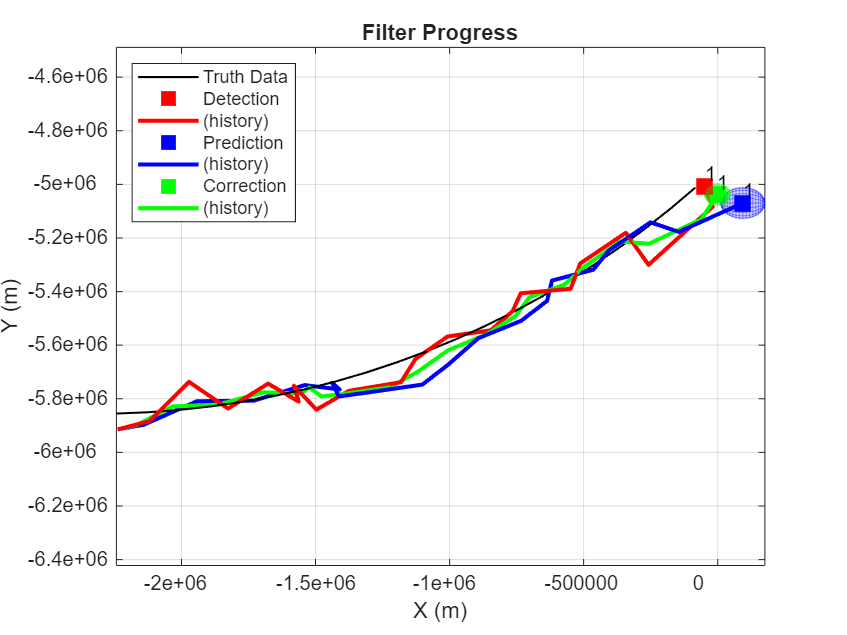

mahalanobisDist = helperRunDataLoop_CV(detectionPosition,truthPosition,filter,time,objectDetection{1}.MeasurementNoise);

Plot Mahalanobis Distance

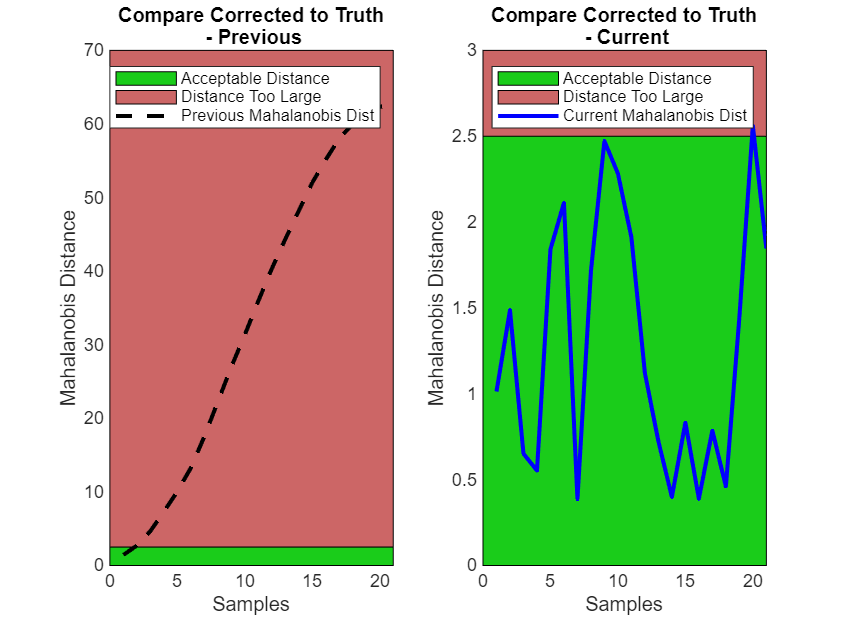

helperPlotMahalanobisDist(mahalanobisDist,mahalanobisDistanceDefault);

# **Takeaways**

Once we have setup our estimation filter to match the motion of the targets within our scenario, we see that our predicted and corrected locations are close to the detections AND that our Mahalanobis distances are around 2 Standard Deviations. In general, it is critical that the estimation filter is adjusted to match the expected dynamics of the targets that you are tracking.

**BONUS!**

In Exercise 2c, we performed the tuning for you. If you are interesting in how this was done, please check the Live Script "TuneFilter_CV.mlx".